# Waste Analysis Demo

Use the ThermoeconomicModel function to make waste analysis

### **Read and create the Thermoeconomic Model**

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\gturbo\gturbo_model.json";
model=ThermoeconomicTool(file,'Debug',false);

### Define Waste Parameters

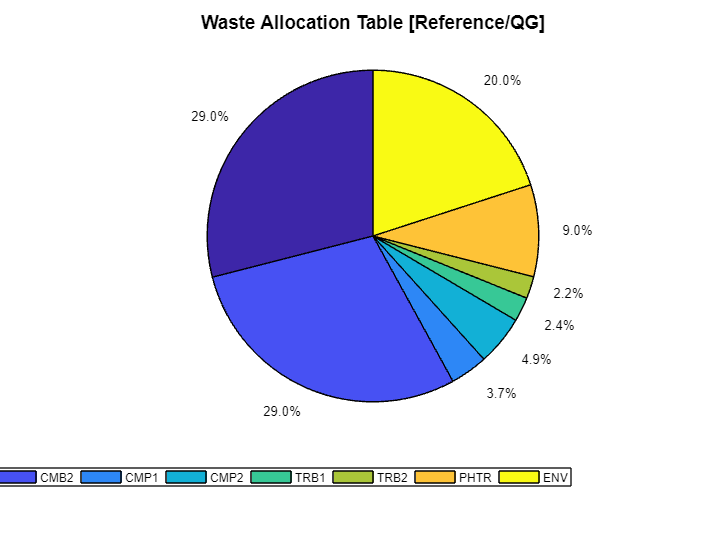

WasteFlows=convertCharsToStrings(model.WasteFlows);
WasteFlow=convertStringsToChars(WasteFlows(1));
model.setWasteType(WasteFlow,'IRREVERSIBILITY');
model.setWasteRecycled(WasteFlow,0.2);
model.graphWasteAllocation(WasteFlow);

### Compute Exergy Cost

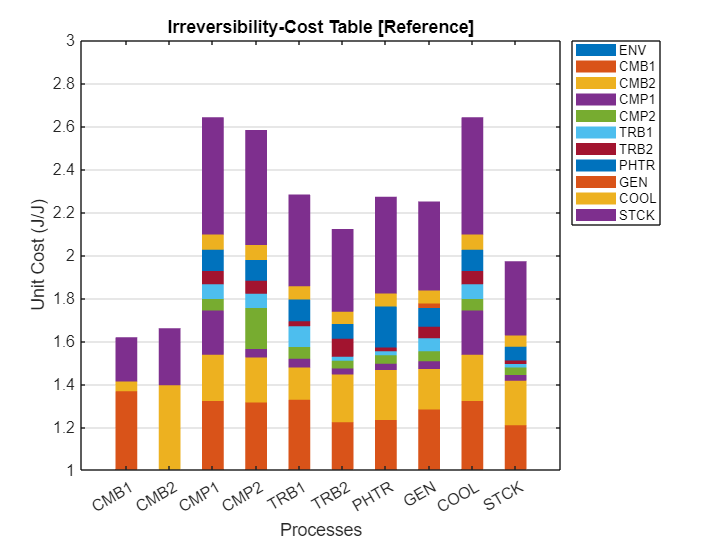

model.wasteAllocation;
graphCost(model,cType.Tables.PROCESS_ICT);

### Recycling Analysis

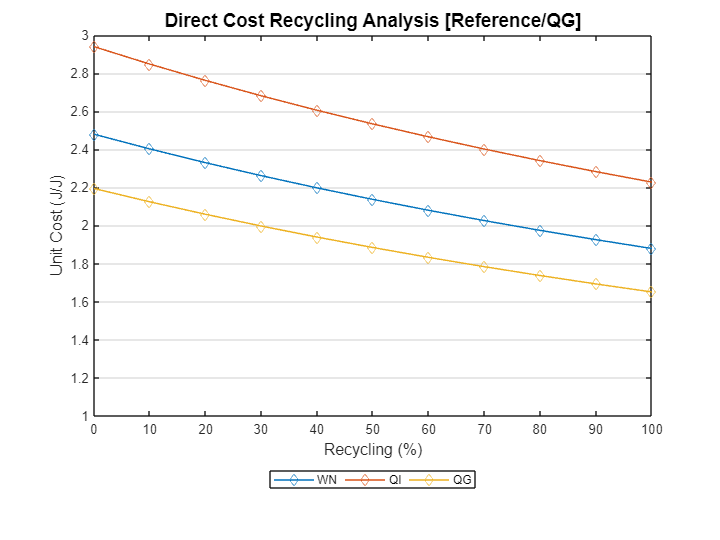

rad=model.recyclingAnalysis(WasteFlow);
rad.graphRecycling;

printResults(rad);

Direct Cost Recycling Analysis (J/J)

 Recycle (%)         WN        QI        QG
--------------------------------------------
      0          2.4792    2.9388    2.1942
     10          2.4020    2.8473    2.1243
     20          2.3296    2.7615    2.0588
     30          2.2615    2.6807    1.9971
     40          2.1973    2.6047    1.9391
     50          2.1368    2.5330    1.8843
     60          2.0796    2.4652    1.8326
     70          2.0255    2.4010    1.7836
     80          1.9742    2.3402    1.7371
     90          1.9255    2.2824    1.6931
    100          1.8792    2.2275    1.6512

